%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%% TUE 5SMB0 System Identification
%%% Assignment 2022
%%% Authors: Jiaxuan Zhang, Yiting Li
%%%%%%%%%%%%%%%%%%%%%%%%%%%


## Data Generation

% [ u , y ] = assignment_sys_36(r)
% clear all
% close all 
% clc


## Part 1: Understanding Saturation and Butterworth Filter

### 1.1

F.num = [ 0.505 , 1.01 , 0.505 ];
F.denom = [ 1 , 0.7478 , 0.2722 ];
F.sys = tf(F.num, F.denom, -1, 'Variable', 'z^-1')


ans =
 
  0.505 + 1.01 z^-1 + 0.505 z^-2
  ------------------------------
  1 + 0.7478 z^-1 + 0.2722 z^-2
 
Sample time: unspecified
Discrete-time transfer function.



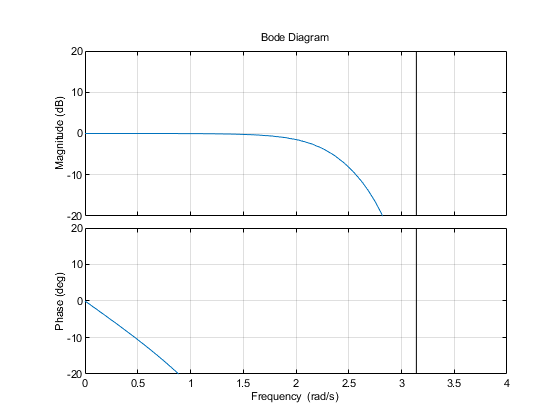

plotopts1 = bodeoptions;
plotopts1.FreqScale = 'linear';
plotopts1.XLim = {[0,4]};
plotopts1. Ylim = {[-20,20]};
plotopts1.Grid = 'on';
bode(F.sys, plotopts1)

% w = 2.195 rad/s is the -3 db point, f = w/2/pi


### 1.2

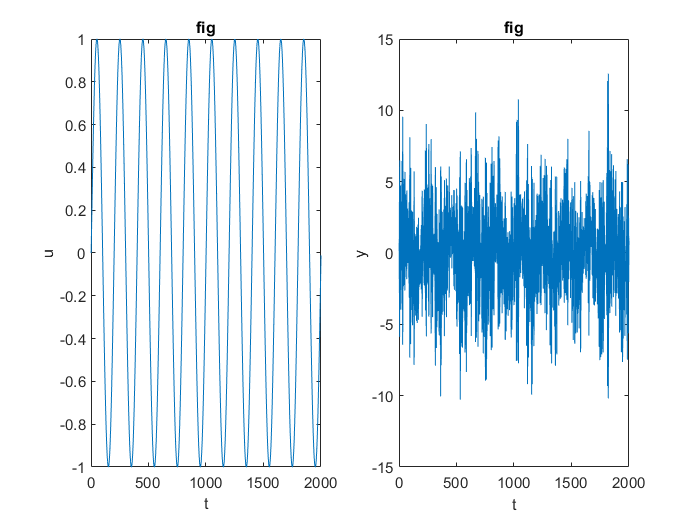

% nu = 100;
% previous_u = -100; 
% for mag=0:1:100
%     r = mag * ones(1,nu);
%     [u,y] = assignment_sys_36(r);
%     u(1)
%     previous_u
%     if (u(1) == previous_u)
%         fprintf("M is equal to %d", u(1));
%         break;
%     end
%     previous_u = u(1);
% end
% 
% % M is equal to 3

N = 2000;
f = 10;
offset = 0;
A = 1;

t = (0 : 1/N : 1)';
r = A * sin(2*pi*f*t) + offset; 

% r = ones([1, N]);
[u,y] = assignment_sys_36(r);


figure;
subplot(1, 2, 1)
plot(u)
xlabel("t");
ylabel("u");
title("fig");

subplot(1, 2, 2)
plot(y)
xlabel("t");
ylabel("y");
title("fig");


% we now can know M is 3



## Part 2: Nonparametric identification

### 2.1 

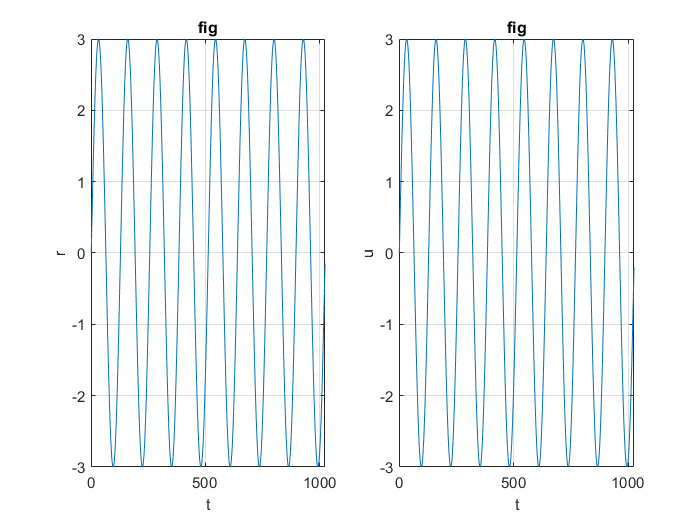

% period = 128;
% N = 1024;
% r = 3*sin( [0: 1: N-1] * pi / period )

% system setup
N = 1024;
Ts = 1;
n_freq = 128;
A = 3;

f = [0: 1: N-1]/n_freq/Ts;
r = A * sin(2*pi*f) + offset;

figure;
subplot(1, 2, 1)
plot(r)
grid on
xlabel("t"); ylabel("r"); title("fig");

[u,y] = assignment_sys_36(r);
subplot(1, 2, 2)
plot(u)
grid on
xlabel("t"); ylabel("u"); title("fig");


figure;
G_ETFE = etfe(iddata(y,u))

G_ETFE =
IDFRD model.
Contains Frequency Response Data for 1 output(s) and 1 input(s).
Response data is available at 128 frequency points, ranging from 0.02454 rad/s to 3.142 rad/s.
 
Sample time: 1 seconds
Output channels: 'y1'
Input channels: 'u1'
Status:                                  
Estimated using ETFE on time domain data.


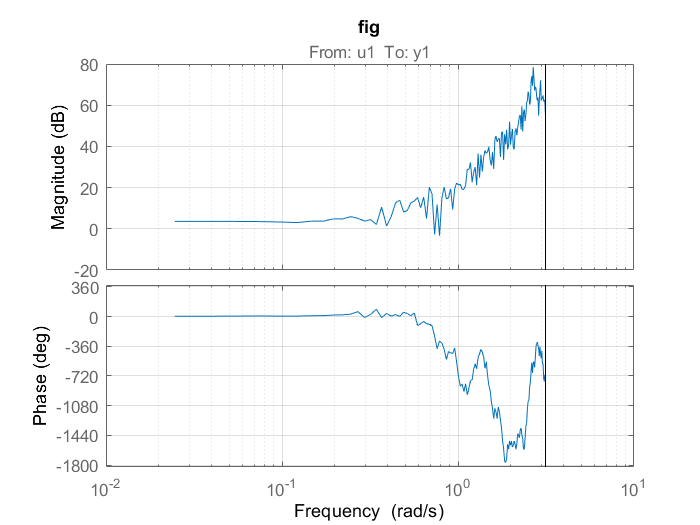

bode(G_ETFE)
grid on
title("fig");

### 2.3

period = 128;
N = 1024;
r = 0*sin( [0: 1: N-1] * pi / period )

r =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


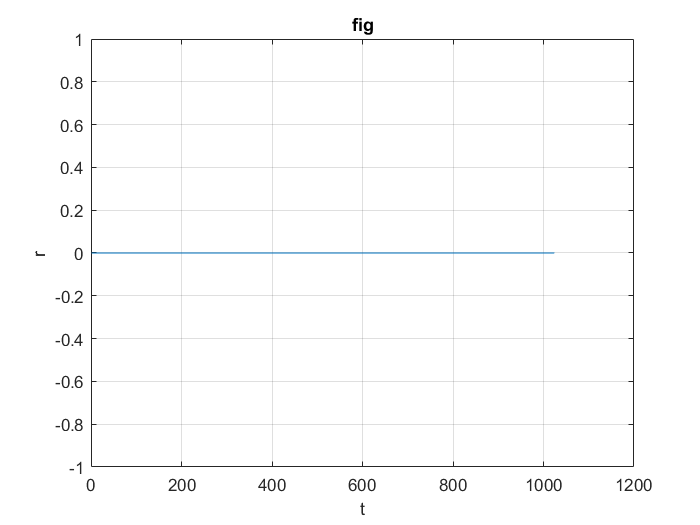

% r = 0 * sin(2*pi*f) + offset

figure;
plot(r)
grid on
xlabel("t"); ylabel("r"); title("fig");

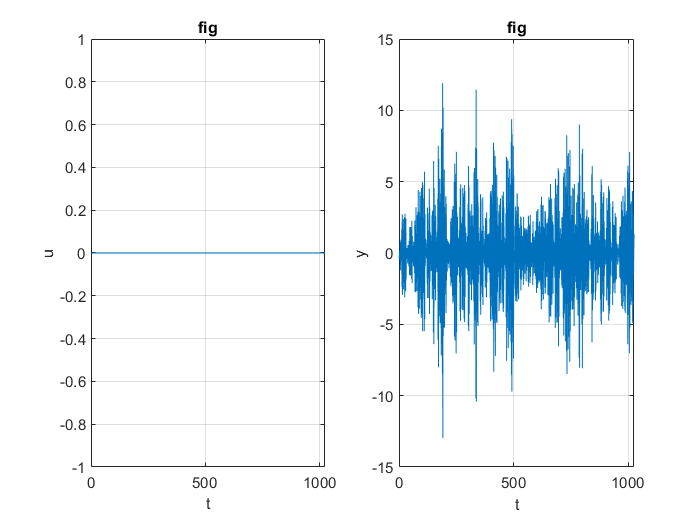


figure;
subplot(1, 2, 1)
[u,y] = assignment_sys_36(r);
plot(u)
grid on
xlabel("t"); ylabel("u"); title("fig");

subplot(1, 2, 2)
plot(y)
grid on
xlabel("t"); ylabel("y"); title("fig");

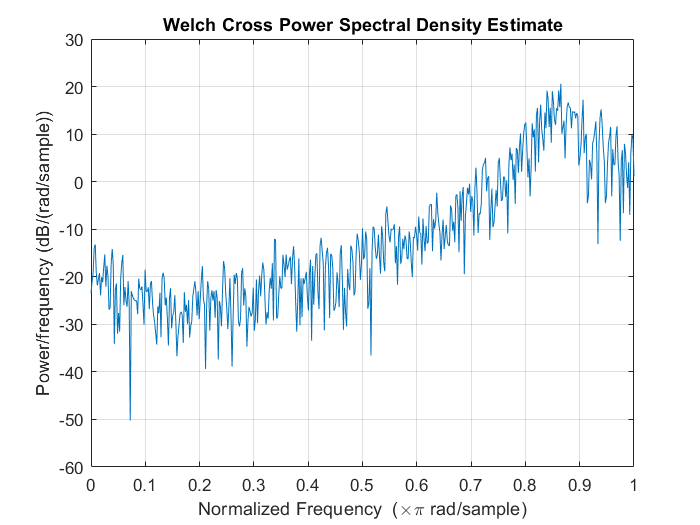


figure;
[Pv, W] = cpsd(y, y, 1024);
cpsd(y, y, 1024)

## Part 3: Expreiment Design

### 3.1

% prefer PRBS




### 3.2

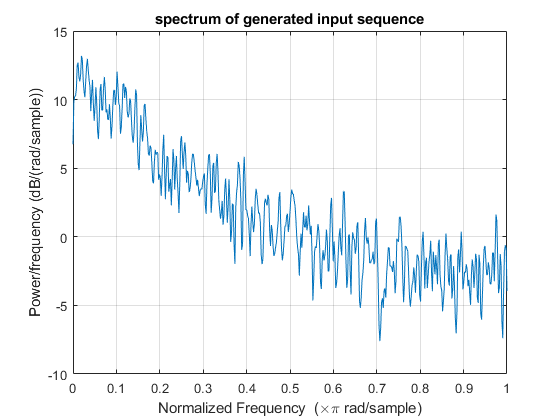

[u,P,w] = Generate_PRBS(0.83, 3000, 3, true);


% I think 0.83 is a good threshold


## Part 4: Parametric identification and validation

### 4.1

## Part 5: Experimental verification of variance estimates

### 5.1

### 5.2

### 5.3

### 5.4

## Function Used

function [u,P,w] = Generate_PRBS(probability, N, mag, plt_flag)
%%%%%%%%%%%%%%%
%% generate PRBS based on:
%% u(t) = u(t-1) with probability p
%% u(t) = -u(t-1) with probability 1-p
%% and may plot spectral density based on setting
%% input: 
%%    P : prbability
%%    N : total input points
%%    mag: output magnitude
%%    plt_flg: if true, plot sepctral density
%% output:
%%    u : generated input sequence
%%    P : spectral density of P
%%    w : spectral density points
%%%%%%%%%%%%%%%%


    % determine the initial entry of u, that is u(1)
    if rand(1,1)>=0.5
        u(1) = mag;
    else
        u(1) = -mag;
    end
    
    % generate sequence
    for i = 2:1:N
        if rand(1,1) <= probability
            u(i) = u(i-1);
        else
            u(i) = -u(i-1);
        end
    end
    
    % get spectrum of generated input sequence
    [P,w] = cpsd(u,u,N);
    
    if (plt_flag == true)
        cpsd(u, u);
        title('spectrum of generated input sequence')
    end
    
end